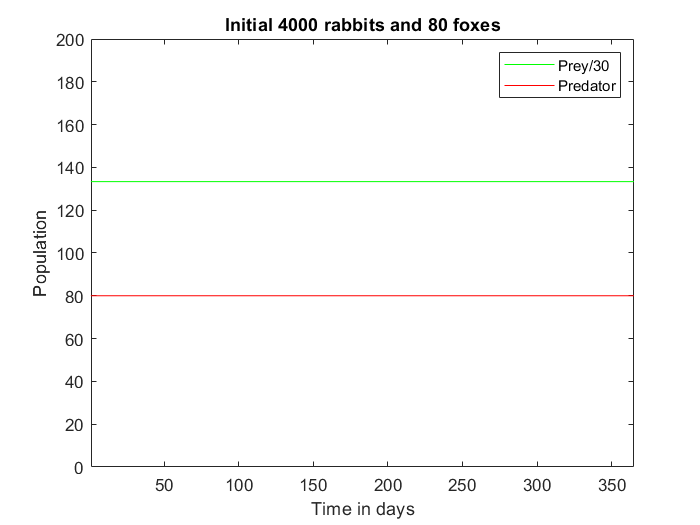

Nprey = zeros(36500,1);
Npred = zeros(36500,1);
dNprey_dt = zeros(36500,1);
dNpred_dt = zeros(36500,1);
% make vectors of size (36500, 1)
Nprey(1) = 4000;
Npred(1) = 80;
% initial value
% change to 5000, 1000 and 4000,80 later on
deltaTau = 0.01;
% step of 0.01 day
Rprey = 0.04;
Rpred = 0.2;
gamma = 0.0005;
epsilon = 0.1;
% input parameters
for i = 1:36500
    dNprey_dt(i) = (Rprey * Nprey(i)) - gamma * Nprey(i) * Npred(i);
    dNpred_dt(i) = (epsilon * gamma * Nprey(i) * Npred(i)) - Rpred * Npred(i);
    Nprey(i + 1) = Nprey(i) + (dNprey_dt(i) * deltaTau);
    Npred(i + 1) = Npred(i) + (dNpred_dt(i) * deltaTau);
end
% applying forward Euler's method
t = 0:0.01:365;
plot(t,Nprey/30,'g');
hold on
plot(t,Npred,'r');
xlabel('Time in days');
ylabel('Population');
title('Initial 4000 rabbits and 80 foxes');
axis([1 365 0 200]);
legend('Prey/30','Predator');
hold off

prey_range = [min(Nprey), max(Nprey)]

prey_range =         4000        4000


pred_range = [min(Npred), max(Npred)]

pred_range =     80    80


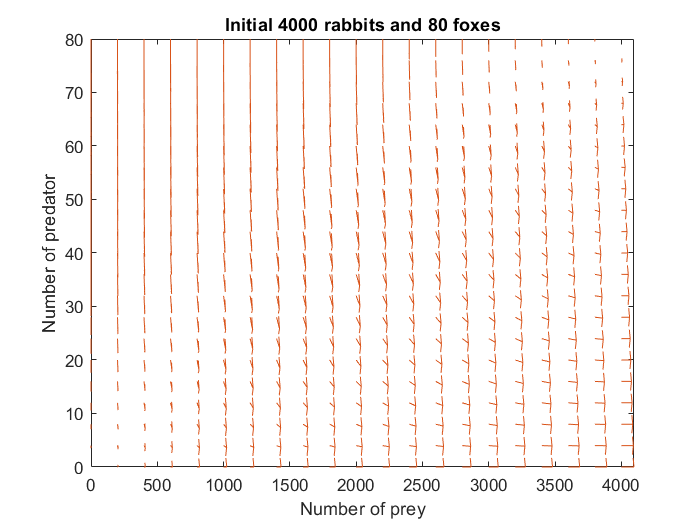

plot(Nprey,Npred);
title('Initial 4000 rabbits and 80 foxes');
xlabel('Number of prey');
ylabel('Number of predator');
hold on;
max_U = max(Nprey);
max_V = max(Npred);
N = 20;
range_U = 0:(max_U/N):max_U;
range_V = linspace(0,max_V,N+1);
[UU,VV] = meshgrid(range_U, range_V);
vel_U = Rprey*UU - gamma*UU.*VV;
vel_V = epsilon*gamma*UU.*VV - Rpred*VV;
h = quiver(range_U,range_V,vel_U,vel_V,0.5);
set (h, "maxheadsize", 0.005);
axis([0 Inf 0 Inf]);
hold off;